## **Load and Pre-Process NBA Game Data**

clear;
clc;
% load table with NBA games from 2014-2018
addpath('data\')
load games.mat


% convert team ID variables to categorical
games.HOME_TEAM_ID = categorical(games.HOME_TEAM_ID);
games.VISITOR_TEAM_ID = categorical(games.VISITOR_TEAM_ID);

% eliminate useless variables
games.TEAM_ID_home = [];
games.TEAM_ID_away = [];
games.GAME_STATUS_TEXT = [];
games.SEASON = [];


% for each game in the data set need the performance of the home and away teams on 10
% previous games. Will use this new information to train the network
numGames = height(games);

% initialize a new training table
trainData = games;

for i =1:numGames
    % calculate stats for the home team
    % exponential moving average calculated: 2/(timeperiod + 1)
    
    timePeriod = 10;
    expAlpha = 2/(timePeriod + 1);
    inverseAlpha = 1 - expAlpha;
    
    % pull out all of the games in which the home team played at home
    previousHomeGames = games(i + 1:end,:);
    homeTeam = games{i,"HOME_TEAM_ID"};
    previousHomeGames = previousHomeGames(previousHomeGames.HOME_TEAM_ID == homeTeam,:);
    
    numPreviousHomeGames = height(previousHomeGames);
   
    if numPreviousHomeGames < timePeriod
         % if we do not have enough observations, discard that game from
         % data set
         oldStatsHome = NaN(1,6);
    else
        % data set is sorted by date, so go backwards to pull the exponential
        % average
        oldStatsHome = previousHomeGames{timePeriod,5:10};
        for j = 1:timePeriod - 1
            newStatsHome = previousHomeGames{timePeriod - j, 5:10};
            oldStatsHome = expAlpha*oldStatsHome + inverseAlpha*newStatsHome;
        end
    end
        
    % plop in the exponential average into the new training table
    trainData{i,5:10} = oldStatsHome;
    
    % now repeat the process for the away team
    
    % pull out all of the games in which the away team played away
    previousAwayGames = games(i + 1:end,:);
    awayTeam = games{i,"VISITOR_TEAM_ID"};
    previousAwayGames = previousAwayGames(previousAwayGames.VISITOR_TEAM_ID == awayTeam,:);
    
    numPreviousHomeGames = height(previousAwayGames);
   
    if numPreviousHomeGames < timePeriod
         % if we do not have enough observations, discard that game from
         % data set
         oldStatsHome = NaN(1,6);
    else
        % data set is sorted by date, so go backwards to pull the exponential
        % average
        oldStatsHome = previousAwayGames{timePeriod,11:16};
        for j = 1:timePeriod - 1
            newStatsHome = previousAwayGames{timePeriod - j, 11:16};
            oldStatsHome = expAlpha*oldStatsHome + inverseAlpha*newStatsHome;
        end
    end
        
    % plop in the exponential average into the new training table
    trainData{i,11:16} = oldStatsHome;
    
end

% save calculations
save('trainData.mat', "trainData")

## **Load Training  & Testing Data (instead of manual processing)**

clear ;
clc;
addpath('data\')
load trainData.mat;
trainData = rmmissing(trainData);
numDatPts = height(trainData);
numTestObservations = floor(0.2*numDatPts);

% OPTIONAL: ADD NEW STATISTICS 
PTS_Diff = trainData.PTS_home - trainData.PTS_away;
FG_Diff = trainData.FG_PCT_home- trainData.FG_PCT_away;
FG3_Diff = trainData.FG3_PCT_home - trainData.FG3_PCT_away;
FT_Diff = trainData.FT_PCT_home - trainData.FT_PCT_away;
AST_Diff = trainData.AST_home - trainData.AST_away;
REB_Diff = trainData.REB_home - trainData.REB_away;

PTS_Divide = trainData.PTS_home ./trainData.PTS_away;
FG_Divide = trainData.FG_PCT_home ./trainData.FG_PCT_away;
FG3_Divide = trainData.FG3_PCT_home ./ trainData.FG3_PCT_away;
FT_Divide = trainData.FT_PCT_home ./ trainData.FT_PCT_away;
AST_Divide = trainData.AST_home ./ trainData.AST_away;
REB_Divide = trainData.REB_home ./ trainData.REB_away;

trainData = addvars(trainData, PTS_Diff, FG3_Diff,FG_Diff,FT_Diff,...
    AST_Diff, REB_Diff, ...
    PTS_Divide, FG3_Divide,FG_Divide,FT_Divide,...
    AST_Divide, REB_Divide, 'Before','HOME_TEAM_WINS');

% define number of features
nFeatures = 24;

% separate out the testing data
[testData , whereTestData] = datasample(trainData, numTestObservations, 'Replace',false);
trainData(whereTestData,:) = [];

## **Format Data and Design Network**


% series of steps to format the data to be "image-like" for input
trainDataMat = trainData{:,5:end-1};
testDataMat = testData{:,5:end-1};

trainDataMat = normalize(trainDataMat);  % feature scaling
response = categorical(trainData{:,end});
trainDataMat = reshape(trainDataMat', [1,1,size(trainDataMat,2),size(trainDataMat,1)]);

testDataMat = normalize(testDataMat);  % feature scaling
responseTest = categorical(testData{:,end});
testDataMat = reshape(testDataMat', [1,1,size(testDataMat,2),size(testDataMat,1)]);


% define the layers of the network
layers = [ ...
    imageInputLayer([1 1 nFeatures]),
    fullyConnectedLayer(10),
    leakyReluLayer,
    fullyConnectedLayer(5),
    leakyReluLayer,
    fullyConnectedLayer(2),
    softmaxLayer,
    classificationLayer
    ];

## **Training Network SGD w/ Momentum**

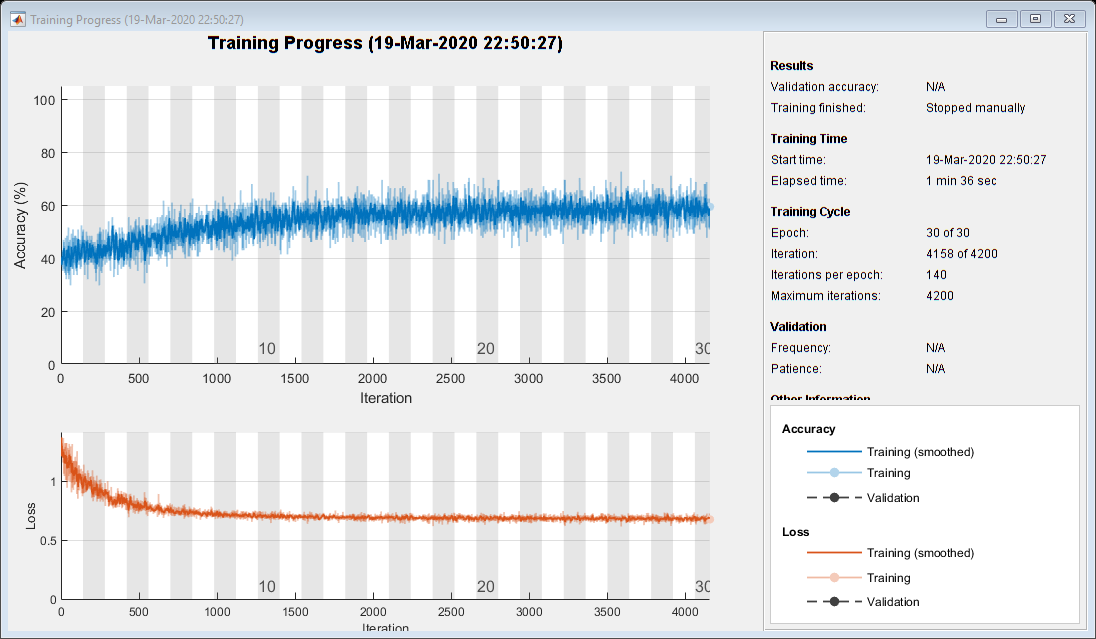

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       38.28% |       1.2088 |      1.0000e-04 |
|       1 |          50 |       00:00:02 |       32.03% |       1.2632 |      1.0000e-04 |
|       1 |         100 |       00:00:03 |       40.63% |       0.9689 |      1.0000e-04 |
|       2 |         150 |       00:00:04 |       37.50% |       1.0172 |      1.0000e-04 |
|       2 |         200 |       00:00:05 |       44.53% |       0.9543 |      1.0000e-04 |
|       2 |         250 |       00:00:06 |       51.56% |       0.8536 |      1.0000e-04 |
|       3 |         300 |  

net =   SeriesNetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


options = trainingOptions('sgdm', 'Plots','training-progress', 'InitialLearnRate', 0.0001, 'Momentum',0.9, 'Shuffle',...
    "every-epoch", 'MiniBatchSize',128, 'GradientThreshold',15);

net = trainNetwork(trainDataMat,response,layers,options)

## **Train Network using RMSProp**

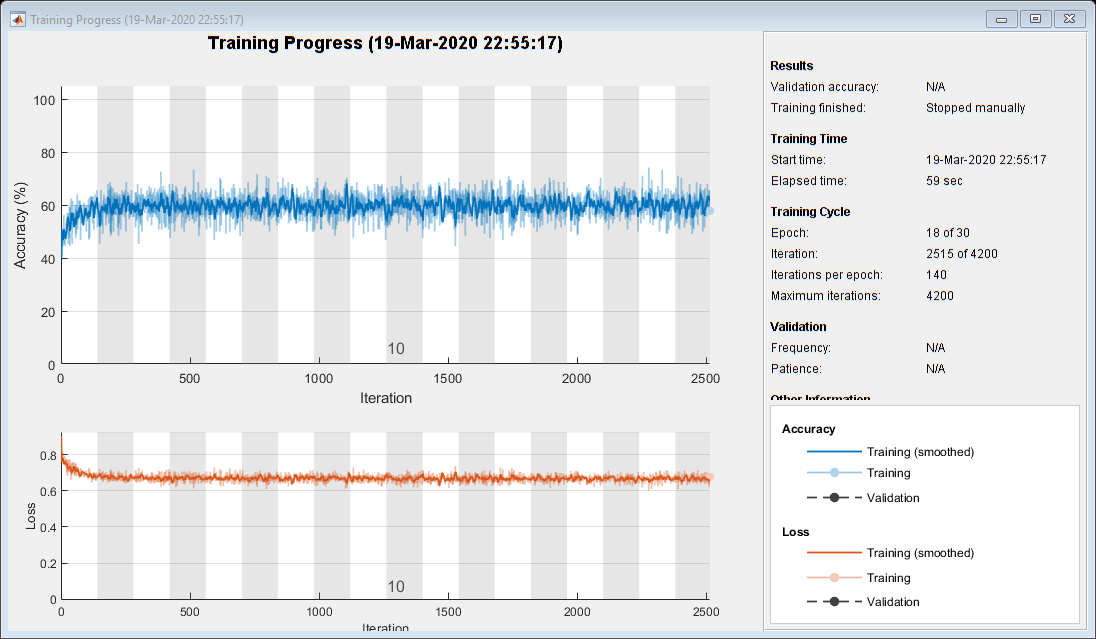

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       43.75% |       0.9051 |          0.0010 |
|       1 |          50 |       00:00:02 |       51.56% |       0.7276 |          0.0010 |
|       1 |         100 |       00:00:03 |       60.16% |       0.6879 |          0.0010 |
|       2 |         150 |       00:00:04 |       45.31% |       0.7216 |          0.0010 |
|       2 |         200 |       00:00:06 |       60.94% |       0.6775 |          0.0010 |
|       2 |         250 |       00:00:07 |       56.25% |       0.6837 |          0.0010 |
|       3 |         300 |  

net =   SeriesNetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


% same sort of concept as SGDM but with an adaptive learning rate. Shrinks
% the learning rate, (and thus the gradient) by an exponenetial moving
% average of past values. This way, more progress is done in the gently
% sloped directions of the parameter space. i.e. if the derivative values
% in the past are really low, we start to up the learning rate in those
% directions

options = trainingOptions('rmsprop', 'Plots','training-progress', 'InitialLearnRate', 0.0001, 'Shuffle',...
    "every-epoch", 'MiniBatchSize',128, 'GradientThreshold',15);

net = trainNetwork(trainDataMat,response,layers,options)

## **Train Network using Adam**

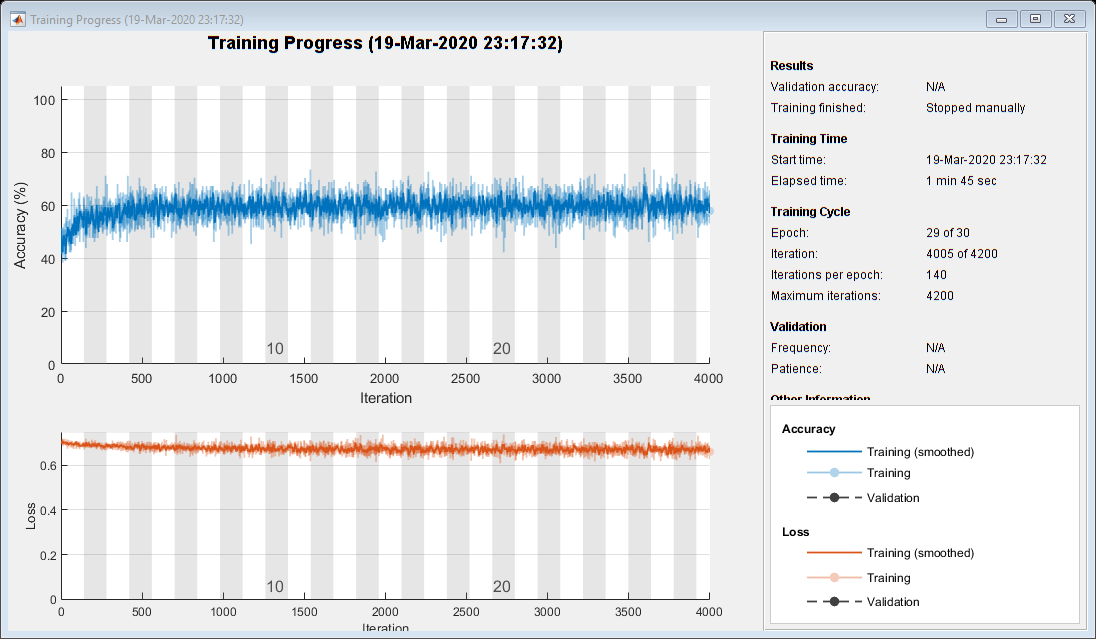

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       41.41% |       0.7096 |      1.0000e-04 |
|       1 |          50 |       00:00:02 |       48.44% |       0.6975 |      1.0000e-04 |
|       1 |         100 |       00:00:03 |       49.22% |       0.7010 |      1.0000e-04 |
|       2 |         150 |       00:00:05 |       56.25% |       0.6923 |      1.0000e-04 |
|       2 |         200 |       00:00:06 |       52.34% |       0.6941 |      1.0000e-04 |
|       2 |         250 |       00:00:07 |       54.69% |       0.6909 |      1.0000e-04 |
|       3 |         300 |  

net =   SeriesNetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


% best seen as RMSProp with momentum, but with less bias

options = trainingOptions('adam', 'Plots','training-progress', 'InitialLearnRate', 0.0001, 'Shuffle',...
    "every-epoch", 'MiniBatchSize',128, 'GradientThreshold',15);

net = trainNetwork(trainDataMat,response,layers,options)

## **Parameter Intialization: Normal Distribution**

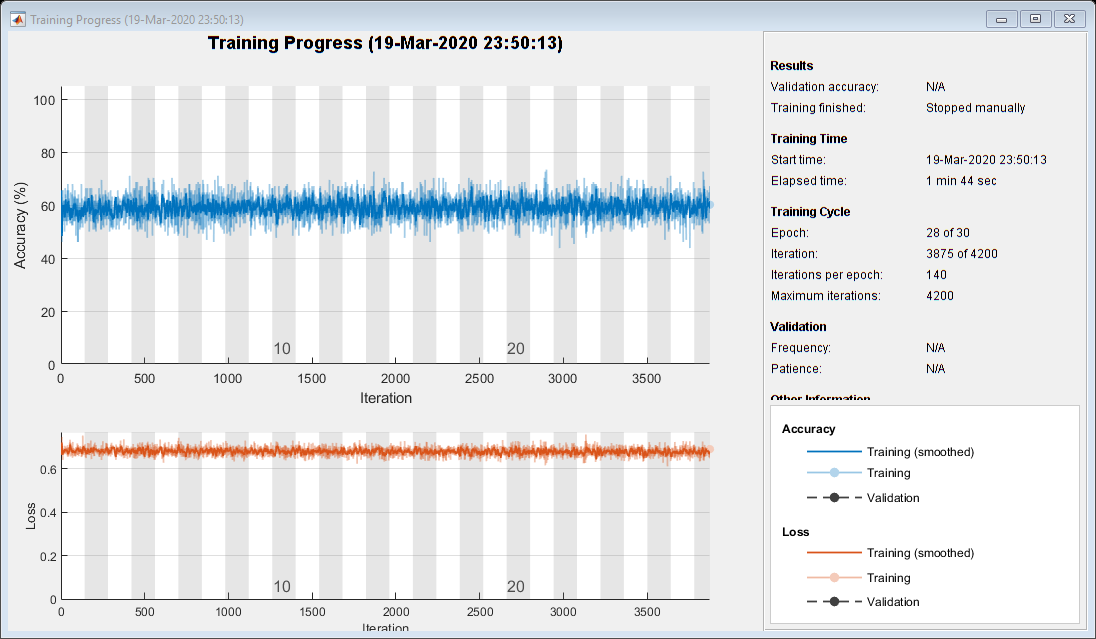

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       62.50% |       0.6793 |      1.0000e-04 |
|       1 |          50 |       00:00:02 |       56.25% |       0.6992 |      1.0000e-04 |
|       1 |         100 |       00:00:03 |       46.09% |       0.7036 |      1.0000e-04 |
|       2 |         150 |       00:00:04 |       54.69% |       0.6491 |      1.0000e-04 |
|       2 |         200 |       00:00:06 |       61.72% |       0.6583 |      1.0000e-04 |
|       2 |         250 |       00:00:07 |       52.34% |       0.7270 |      1.0000e-04 |
|       3 |         300 |  

net =   SeriesNetwork with properties:

         Layers: [10×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


% Make the network slightly deeper in hopes of improving accuracy
layers = [ ...
    imageInputLayer([1 1 nFeatures]),
    fullyConnectedLayer(10),
    leakyReluLayer,
    fullyConnectedLayer(7),
    leakyReluLayer,
    fullyConnectedLayer(5),
    leakyReluLayer,
    fullyConnectedLayer(2),
    softmaxLayer,
    classificationLayer
    ];

% intialize layers 2,4, & 6 (fully connected layers) with different
% initializers
if 0
    layers(2).WeightsInitializer = 'he';
    layers(4).WeightsInitializer = 'he';
    layers(6).WeightsInitializer = 'he';
else
    layers(2).WeightsInitializer = 'orthogonal';
    layers(4).WeightsInitializer = 'orthogonal';
    layers(6).WeightsInitializer = 'orthogonal';
end


options = trainingOptions('sgdm', 'Plots','training-progress', 'InitialLearnRate', 0.0001, 'Momentum',0.9, 'Shuffle',...
    "every-epoch", 'MiniBatchSize',128, 'GradientThreshold',15);

net = trainNetwork(trainDataMat,response,layers,options)

## Adding Batch Normalization

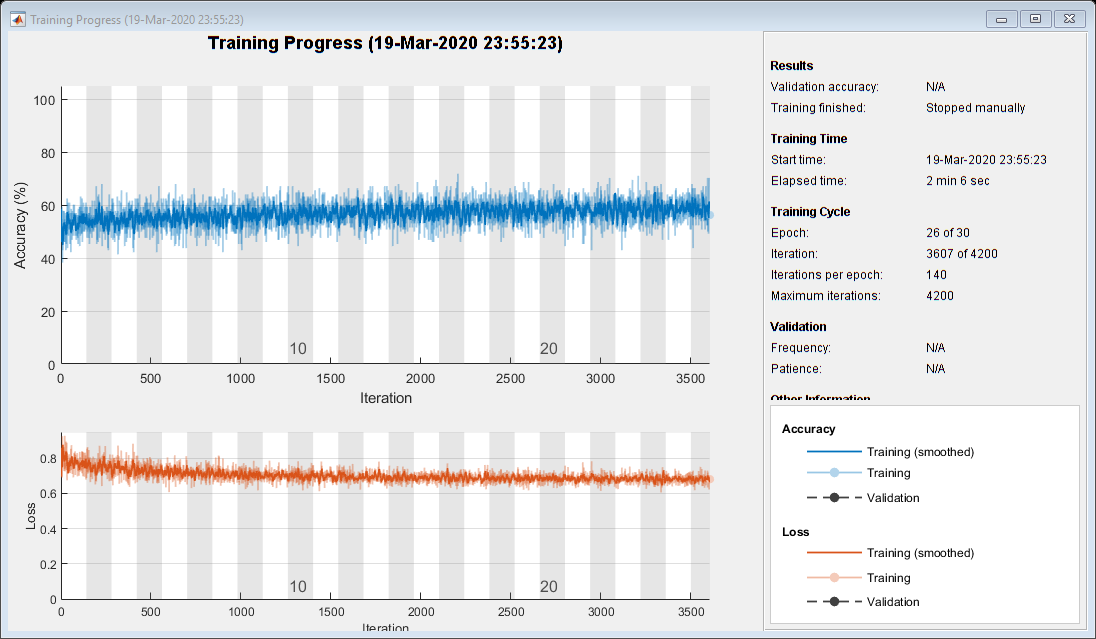

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       58.59% |       0.7450 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       45.31% |       0.8038 |      1.0000e-04 |
|       1 |         100 |       00:00:04 |       56.25% |       0.7009 |      1.0000e-04 |
|       2 |         150 |       00:00:06 |       56.25% |       0.7521 |      1.0000e-04 |
|       2 |         200 |       00:00:08 |       59.38% |       0.7134 |      1.0000e-04 |
|       2 |         250 |       00:00:09 |       50.78% |       0.7676 |      1.0000e-04 |
|       3 |         300 |  

net =   SeriesNetwork with properties:

         Layers: [13×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


% redefine the network with batch normalization
layers = [ ...
    imageInputLayer([1 1 nFeatures]),
    fullyConnectedLayer(10),
    batchNormalizationLayer,
    leakyReluLayer,
    fullyConnectedLayer(7),
    batchNormalizationLayer,
    leakyReluLayer,
    fullyConnectedLayer(5),
    batchNormalizationLayer,
    leakyReluLayer,
    fullyConnectedLayer(2),
    softmaxLayer,
    classificationLayer
    ];

options = trainingOptions('sgdm', 'Plots','training-progress', 'InitialLearnRate', 0.0001, 'Momentum',0.9, 'Shuffle',...
    "every-epoch", 'MiniBatchSize',128, 'GradientThreshold',15);

net = trainNetwork(trainDataMat,response,layers,options)

## Test Network For Generalization Accuracy

% test set accuracy
predNetwork = predict(net, trainDataMat);
predNetwork = predNetwork(:,1) < predNetwork(:,2);

acc = sum(predNetwork == (response== '1'))./length(trainDataMat(:,:,1,:))

acc = 0.5864


% generalization set accuracy
predNetwork = predict(net, testDataMat);
predNetwork = predNetwork(:,1) < predNetwork(:,2);

acc = sum(predNetwork == (responseTest== '1'))./length(testDataMat(:,:,1,:))

acc = 0.5753